% Task 1 %
clear;clc;

% Load
load data_1.mat

% 命名规则：
% ref: seq_ref截取出的0~0.01s的信号
% ref_f: ref的频域信号
% ref_shift: ref经过频移后的时域信号
% ref_shift_f: ref_shift的频域信号
% 以此类推...

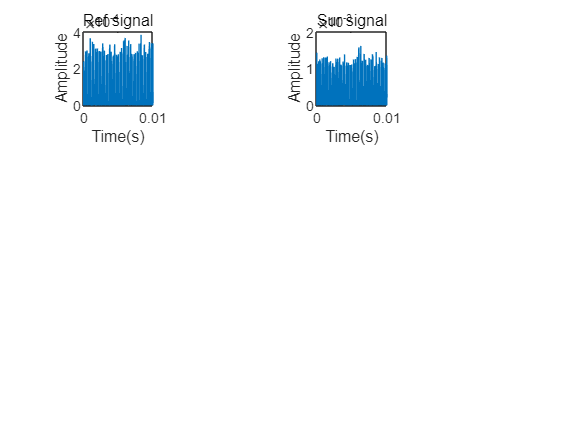

% 画初始ref,sur信号的时域图

part = 250000; % 截取0~0.01s的数据
ref = seq_ref(1:part);
sur = seq_sur(1:part);
t = linspace(0,0.01,part);
figure;
subplot(3,4,1);
plot(t,abs(ref)),
xlabel('Time(s)'),
ylabel('Amplitude'),
title('Ref signal');

subplot(3,4,3);
plot(t,abs(sur)),
xlabel('Time(s)'),
ylabel('Amplitude'),
title('Sur signal');

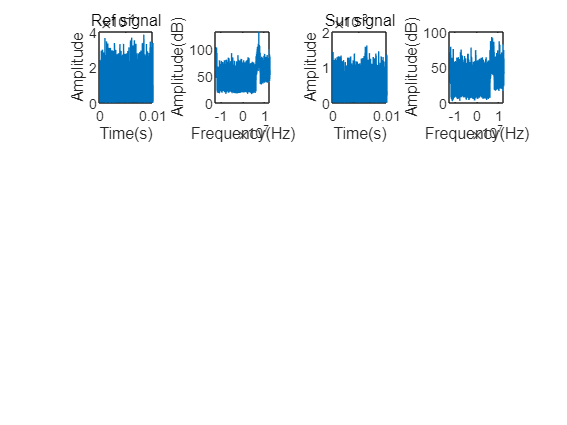

% 画初始ref,sur信号的频域图

part = 250000;
ref_f = fft(ref);
tau = 0.01/part;
wk = (-pi/tau + (0:part-1) * 2*pi/part/tau)/2/pi;
subplot(3,4,2);
plot(wk,abs(20*log10(fftshift(ref_f)))),
xlabel('Frequency(Hz)'),
ylabel('Amplitude(dB)');
sur_f = fft(sur);
subplot(3,4,4);
plot(wk,abs(20*log10(fftshift(sur_f)))),
xlabel('Frequency(Hz)'),
ylabel('Amplitude(dB)');

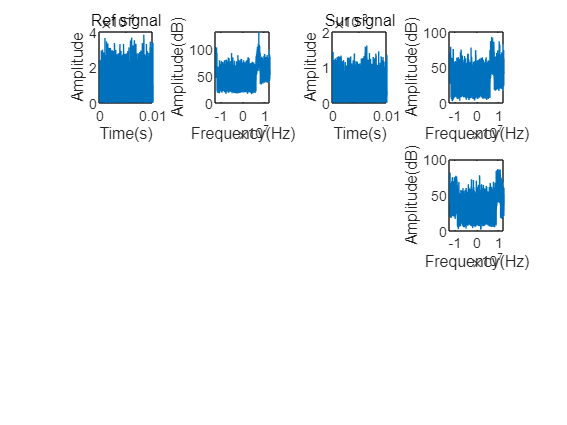

% 画频移过后的ref,sur信号频域图

f0 = 2900000;
t = linspace(0,0.01,part);
sur_shift = sur .* exp(1i*2*pi*f0.*t);
subplot(3,4,8);
plot(wk,abs(20*log10(fftshift(fft(sur_shift))))),
xlabel('Frequency(Hz)'),
ylabel('Amplitude(dB)');

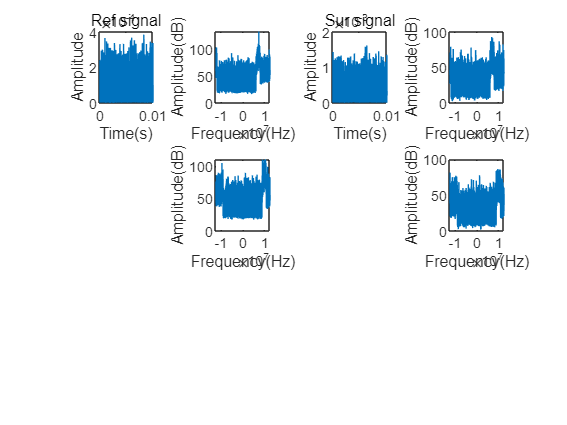

f0 = 2800000;
t = linspace(0,0.01,part);
ref_shift = ref .* exp(1i*2*pi*f0.*t);
subplot(3,4,6);
plot(wk,abs(20*log10(fftshift(fft(ref_shift))))),
xlabel('Frequency(Hz)'),
ylabel('Amplitude(dB)');

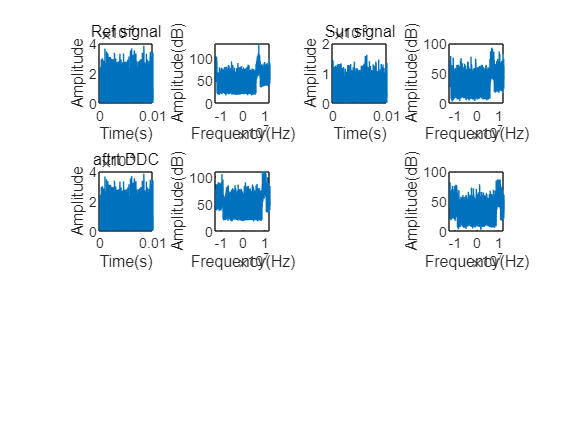

% 画频移过后的ref,sur信号时域图

subplot(3,4,5);
plot(t,abs(ref_shift)),
xlabel('Time(s)'),
ylabel('Amplitude'),
title('aftrt DDC');

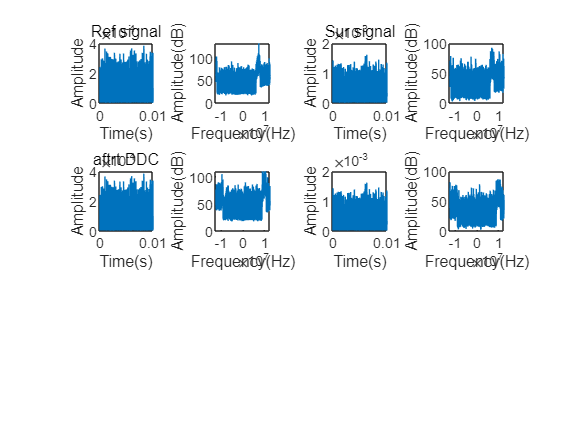

subplot(3,4,7);
plot(t,abs(sur_shift)),
xlabel('Time(s)'),
ylabel('Amplitude');

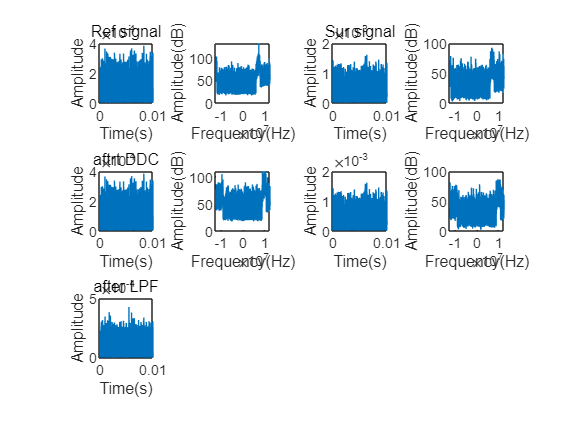

% 画低通滤波后的sur,ref时域图

% LPF 低通的截止频率为0.9*10^7
[b,a] = butter(10,0.88*10^7*2/f_s,'low');
ref_shift_butter = filter(b,a,ref_shift);
sur_shift_butter = filter(b,a,sur_shift);

subplot(3,4,9);
plot(t,abs(ref_shift_butter)),
xlabel('Time(s)'),
ylabel('Amplitude'),
title('after LPF');

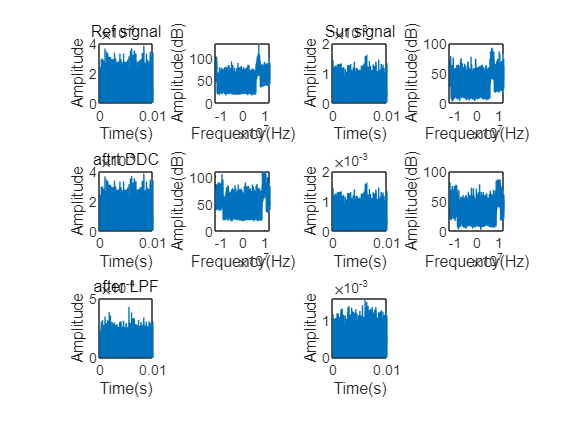

subplot(3,4,11);
plot(t,abs(sur_shift_butter)),
xlabel('Time(s)'),
ylabel('Amplitude');

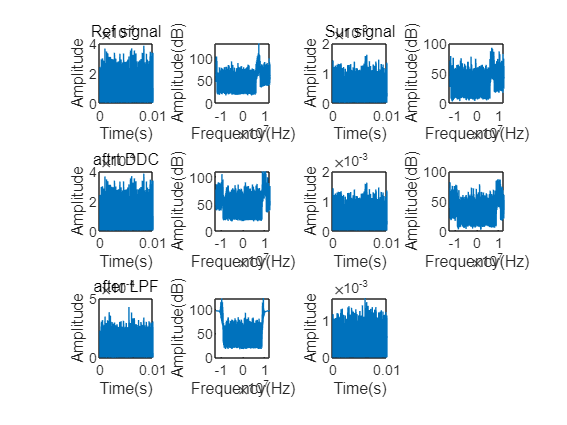

% 画低通后的sur,ref频域图

subplot(3,4,10);
plot(wk,abs(20*log10(fftshift(fft(ref_shift_butter))))),
xlabel('Frequency(Hz)'),
ylabel('Amplitude(dB)');

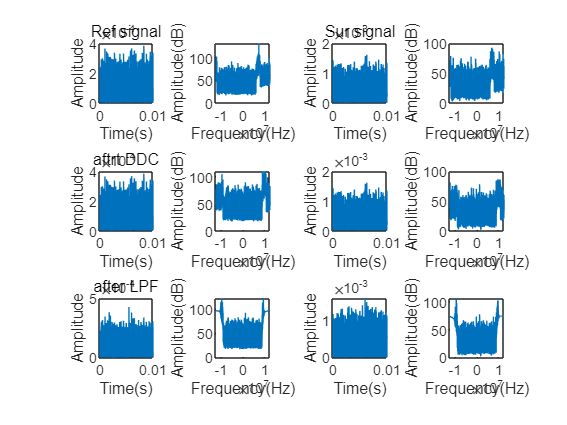

subplot(3,4,12);
plot(wk,abs(20*log10(fftshift(fft(sur_shift_butter))))),
xlabel('Frequency(Hz)'),
ylabel('Amplitude(dB)');

Task 1 Output: